%% Setup
clear all
close all
clc
warning off;

cd /Users/rogerchen/Documents/MATLAB/rc_thesis_irf/Emp_App/RZ_Active_Rep/

%% Input Specs
timesample=1; % 2 means 1889-2015; 2 means post WWII
statechoice=1;  % 1 means default unemp threshold; 2 means default ZLB threshold
shockchoice=1; % 1 means news shock; 2 means BP shock
transformation=1; % 1 means Gordon-Krenn; 2 means Hall-Barro-Redlick
taxchoice=0; %0 means no taxes as control; 1 means ad taxy as a control
datafirstdiff=0; % means to difference the key GDP / Gov Spending series 

trend=0; %4 means quartic; 2 means quadratic; 0 means no trend  
nlag=4;% number of lags of control variables
opt=0; % 0 means Newey-West with bandwidth=i; 1 means optimal bandwidth (takes much longer to run)'

if transformation==1
    disp('Gordon-Krenn')
elseif transformation==2
    disp('Hall-Barro-Redlick')
end

Gordon-Krenn



if shockchoice==1
    disp('News shock')
elseif shockchoice==2
    disp('BP shock')
end

News shock



hor=20; % horizon for IRFs
clevel= 1.96; % confidence level % 1.96  1.64;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
run('figure_irfs_multipliers_setup.m')

ans = 0.3584

## Estimate linear SVAR LP Averaged Estimator + Bootstrapped P Values

y = y_tvar; % get generated y matrix for trivariate VAR
% VAR specs
p = 4;

[T, k] = size(y);
Y = y(p+1:end, :);
ylag = lagmatrix(y, [1:p]);
ylag = ylag(p+1:end, :);
const = ones(T-p, 1);

X = [const, ylag];
beta = (X' * X) \ (X' * Y);
resid = Y - X * beta;

Now boostrap using the reduced-form VAR estimates to construct bootstrap dependent variable

TT = T-p

TT = 501


% bootstrap setup variables
B = 99;
horizon = 20;
bs_dv = zeros(TT, 3, B);
bs_irf = zeros(B, horizon, 2);

% settings for VARLP_Avg estimation
rpos = 2;
transformation = 1;
clevel = 1.96

clevel = 1.9600

opt = 0;
nlag = p;
bs = 0; % bias correction?

% OPTIONAL - demean residuals
% resid = resid - mean(resid);

for i=1:B
    y_bs = zeros(TT, 3);
    y_bs(1:p, :) = Y(1:p, :); % initialise the first p rows of the bootstrap dependent variable vector with the observed y
    resid_sample = datasample(resid, TT, 'Replace', true);
    
    for j=p+1:TT
        % define our starting params
        % generate VAR terms
        plagy = [];
        for l=1:p
            plagy = [plagy, y_bs(j-l, :)];
        end
        x_bs = [1, plagy];
        res = [resid(j, 1), resid_sample(j, 2:3)];
        y_bs(j, :) = x_bs*beta + res;
    end
    bs_dv(:, :, i) = y_bs;
    
    % prepare data
    data = y_bs(:, 2:3);
    x = y_bs(:, 1);
    ylag = lagmatrix(y_bs, [1:p]);
    % remove the first p obs
    ylag = ylag(p+1:end, :);
    data = data(p+1:end, :);
    x = x(p+1:end, :);
    X = [ones(size(x, 1), 1), x, ylag];
    [irf, ~] = linSVARLP_avg(data, X, horizon, rpos, transformation, clevel, opt, nlag, bs, 0);
    bs_irf(i, :, 1) = irf(1, :);
    bs_irf(i, :, 2) = irf(2, :);
end

clevel = 1.96;
bs_irf_se(1, :) = var(bs_irf(:,:,1)).^(1/2);
point_irf(1, :) = mean(bs_irf(:,:,1));
bs_irf_se(2, :) = var(bs_irf(:,:,2)).^(1/2);
point_irf(2, :) = mean(bs_irf(:,:,2));

% CI
bs_irf_ci(1,:,1)=point_irf(1,:)-clevel*bs_irf_se(1, :);
bs_irf_ci(1,:,2)=point_irf(1,:)+clevel*bs_irf_se(1, :);
bs_irf_ci(2,:,1)=point_irf(2,:)-clevel*bs_irf_se(2, :);
bs_irf_ci(2,:,2)=point_irf(2,:)+clevel*bs_irf_se(2, :);


fig = figure;
j = 1

j = 1

subplot(2,1,1);
hold on
plot(point_irf(j,:), 'LineStyle','-','LineWidth', 1.5, 'Color', 'black')
plot(bs_irf_ci(j,:,1), 'LineStyle','--', 'LineWidth',1, 'Color', [0.5 0.5 0.5])
plot(bs_irf_ci(j,:,2), 'LineStyle','--', 'LineWidth',1, 'Color', [0.5 0.5 0.5])
legend('Point Estimate', '95% CI')
ylabel('Gov Spending')
xlabel('Horizon (quarters)')

j = 2

j = 2

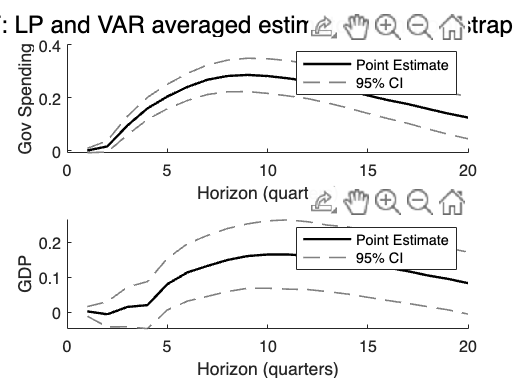

subplot(2,1,2);
hold on
plot(point_irf(j,:), 'LineStyle','-','LineWidth', 1.5, 'Color', 'black')
plot(bs_irf_ci(j,:,1), 'LineStyle','--', 'LineWidth',1, 'Color', [0.5 0.5 0.5])
plot(bs_irf_ci(j,:,2), 'LineStyle','--', 'LineWidth',1, 'Color', [0.5 0.5 0.5])
legend('Point Estimate', '95% CI')
ylabel('GDP')
xlabel('Horizon (quarters)')

sgtitle('IRF: LP and VAR averaged estimator with bootstrap CIs')


% saveas(fig, 'avg_estimator_bootstrap.png')